Rocky_closed_loop_poles.m

1) Symbolically calculates closed loop transfer function of PI disturbannce rejection control system for Rocky. 

Currently no motor model (M =1).Placeholder for motor model (1st order TF)

2) Specify location of (target)poles based on desired reponse. The number of poles = denominator polynomial of closed loop TF

3) Extract the closed loop denomiator poly and set = polynomial of target poles

4) Solve for Ki and Kp to match coefficients of polynomials. In general, this will be underdefined and will not be able to place poles in exact locations. 

 5) Plot impulse response to see closed-loop behavior. 

 based on code by SG. last modified 3/12/21 C

syms s a b l g kp ki jp ji ci  % define symbolic variables

Hvtheta = -(s/l)/(s^2-(g/l));       % TF from velocity to angle of pendulum

K = kp + ki/s; % TF of the PI angle controller
M = a*b/(s+a) % TF of motor

$$M = \frac{a\,b}{a+s}$$

tau = 0.103/2;
k= 0.0027;

%closed loop transfer function from disturbance d(t)totheta(t)
Nested_loop = M / (1 + M*(jp + ji/s + ci/s^2));
Hcloop = 1/(1-Hvtheta*Nested_loop*K);
pretty(simplify(Hcloop)) % to display the total transfer function

                                1
- ------------------------------------------------------------
                          2
                     a b s  (ki + kp s)
  -------------------------------------------------------- - 1
        2          2    3                    2
  (- l s  + g) (a s  + s  + a b ci + a b jp s  + a b ji s)



% Substitute parameters and solve
% system parameters
g = 9.81;
l = 0.4822; %effective length m
a = 1/tau;
b = k;
Hcloop_sub = subs(Hcloop); % sub parameter values into Hcloop
% specify locations of the target poles,
% choose # based on order of Htot denominator
% e.g., want some oscillations, want fast decay, etc.

omega_n = 4.5080; % natural frequency
omega_chosen = omega_n - 1; % oscillate quickly > oscillate slowly

p1 = -1 + 1*omega_chosen*i;
p2 = -1 - 1*omega_chosen*i;
p3 = -5;
p4 = -8;
p5 = -10;

% target characteristic polynomial
% if motor model (TF) is added, order of polynomial will increase
tgt_char_poly = (s-p1)*(s-p2)*(s-p3)*(s-p4)*(s-p5);
% get the denominator from Hcloop_sub
[n, d] = numden(Hcloop_sub);
% find the coefficients of the denominator polynomial TF
coeffs_denom = coeffs(d, s);
% divide though the coefficient of the highest power term
coeffs_denom = coeffs(d, s)/(coeffs_denom(end));
% find coefficients of the target characteristic polynomial
coeffs_tgt = coeffs(tgt_char_poly, s);
% solve the system of equations setting the coefficients of the
% polynomial in the target to the actual polynomials
solutions = solve(coeffs_denom(1:5) == coeffs_tgt(1:5),kp,ki,jp,ji,ci)

solutions = struct with fields:
    kp: [1×1 sym]
    ki: [1×1 sym]
    jp: [1×1 sym]
    ji: [1×1 sym]
    ci: [1×1 sym]


% display the solutions as double precision numbers
kp = real(double(solutions.kp))

kp = 3.6805e+03

ki = real(double(solutions.ki))

ki = 1.6705e+04

jp = real(double(solutions.jp))

jp = 106.4815

ji = real(double(solutions.ji))

ji = -2.8709e+03

ci = real(double(solutions.ci))

ci = -4.9901e+03


% Location of the poles of the closed-loop TF.
% NOTE there are only 2 unknowns but 3 polynomial coefficients so
% the problem is underdetermined and the closed loop poles don't exact
% match the target poles.
% use trial-and-error to tune response
closed_loop_poles = vpa (roots(subs(coeffs_denom)), 4);
% Plot impulse response of closed-loop system
TFstring = char(subs(Hcloop));
% Define 's' as transfer function variable
s = tf('s');
% Evaluate the expression
eval(['TFH = ',TFstring]);

TFH =
 
  2.656e42 s^8 + 1.18e44 s^7 + 8.356e44 s^6 - 1.086e46 s^5 - 3.159e46 s^4 + 1.721e47 s^3 + 2.745e47 s^2
  -----------------------------------------------------------------------------------------------------
  2.656e42 s^8 + 1.18e44 s^7 + 1.899e45 s^6 + 1.461e46 s^5 + 6.208e46 s^4 + 1.721e47 s^3 + 2.745e47 s^2
 
Continuous-time transfer function.



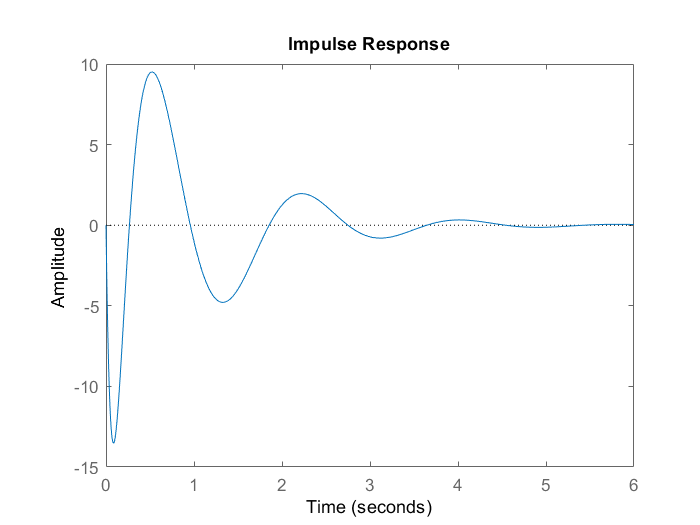

figure (1)
impulse(TFH); %plot the impulse reponse

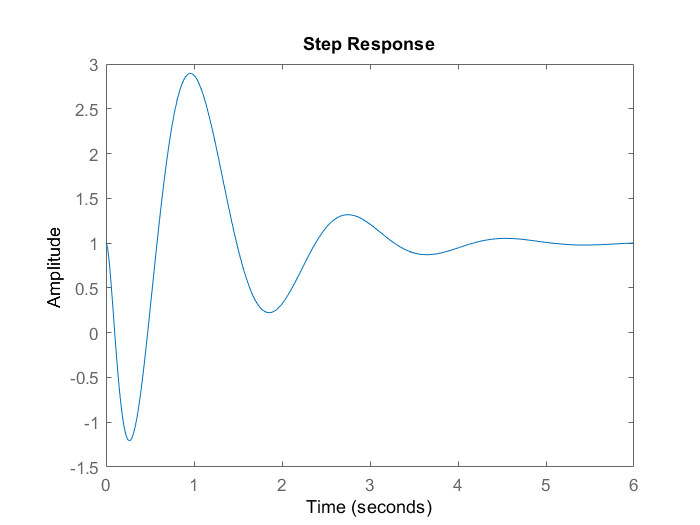

figure(2)
step(TFH)

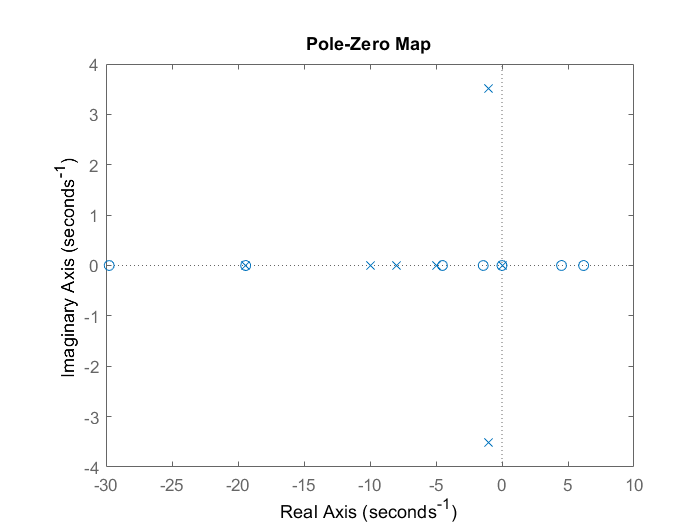

pzplot(TFH)